# 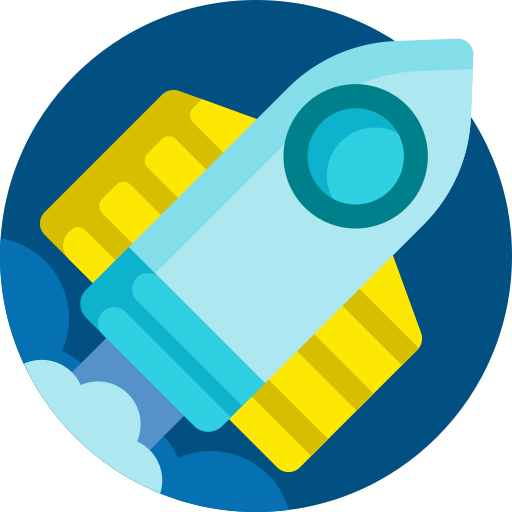

# **MEC3079S: Control Systems**

# Chapter 9 — Stability of closed-loop systems

## 9.1 Introduction

As shown for open-loop systems in the previous chapters, stability is a key requirement of a system in order to have the potential to meet a set of performance specifications. Unstable systems result in diverging output responses that render the concepts of settling time, overshoot, etc irrelevant, which means that we have no chance in controlling the output. 

This chapter will extend the concept of stability to that of closed-loop systems. It will be shown that the idea of closed-loop stability is analogous to that of open-loop systems and is predicated on the pole location(s) in the s-plane. We will then explore frequency-domain methods that can be used to assess system closed-loop stability given knowledge of the open-loop system's frequency response. This methodology will form the basis of future frequency-domain analysis and design techniques in this course.

## 9.2 General stability

### 9.2.1 Closed-loop poles and zeros

In a previous chapter the concept of stability was introduced, which is based on the location of the poles in the s-plane. Specifically, if *all* poles of a system lie in the open left half-plane of the s-plane, or OLHP (requiring the real components of all poles to be strictly less than zero), the system is deemed strictly (or BIBO) stable. This concept can be extended to closed-loop systems without loss of generality. Consider the two equivalent closed-loop systems in Figure 9.1

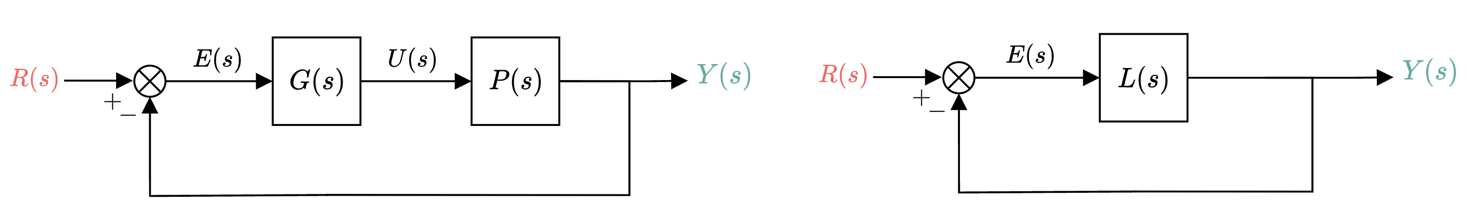

**Figure 9.1: **Equivalent closed-loop systems under consideration.

where $L(s)=P(s)G(s)$ is the open-loop transfer function. If $R(s)$ is our setpoint (or desired output signal) and we would like output $Y(s)$ to approach $R(s)$ in some sense, then we need to first ensure that the transfer behaviour from $R(s)$ to $Y(s)$ is stable. We can define $L(s)$ as a ratio of polynomials

$L(s)=\frac{N(s)}{D(s)}$,

where the roots of $N(s)=0$ are equal to the open-loop zeros and the roots of $D(s)=0$ correspond to the open-loop poles. The transfer behaviour from $R(s)$ to $Y(s)$ is easily determined as

$\frac{Y(s)}{R(s)}=T(s)=\frac{L(s)}{1+L(s)}$,

where $T(s)$ is the complementary sensitivity function as introduced in **Chapter 8**. This can be reposed as a ratio of polynomials from $L(s)$, namely

$\frac{L(s)}{1+L(s)}=\frac{N(s)/D(s)}{1+N(s)/D(s)}=\frac{N(s)}{N(s)+D(s)}$.

The above result implies that the zeros of $L(s)$, arising from solving $N(s)=0$, will be equivalent to the zeros of $T(s)$. The closed-loop poles are determined by finding the roots of $N(s)+D(s)=0$. Therefore *both *the open-loop poles *and* open-loop zeros affect the closed-loop poles (an important insight that we will explore in a later chapter). We can also determine the closed-loop poles by finding the roots of 

$1+L(s)=1+N(s)/D(s)=0$,

which after multiplying both sides by $D(s)$ is equivalent to


$$N(s)+D(s)=0$$


The closed-loop system is then defined as stable if the closed-loop poles lie in the open left half-plane of the s-plane.

%Example
s = tf('s');
L = (1+s/5)/(1+s/20);
T = feedback(L,1);

[pole_L,zero_L] = pzmap(L)

pole_L = -20

zero_L = -5

[pole_T,zero_T] = pzmap(T)

pole_T = -8

zero_T = -5

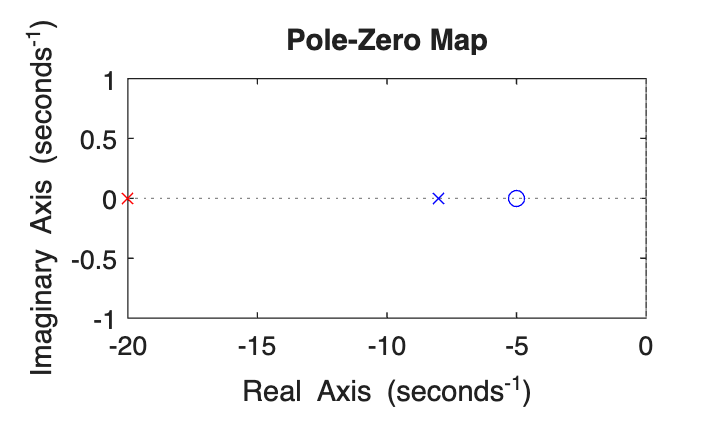


figure,hold on
pzmap(L,'r')
pzmap(T,'b')

Assuming we knew $L(s)$, we could then find the roots of $1+L(s)$ in order to assess whether the closed-loop system is stable. While there is technically nothing wrong with this exercise, the process of continually checking closed-loop stability based on pole location (by finding the roots of $1+L(s)=0$) is time-consuming and inefficient. However, it turns out that there is actually a very convenient approach that we can use to assess closed-loop stability based on the frequency response, without having to analytically determine the closed-loop pole locations every time. This concept is presented in the following sections.

### 9.2.2 The critical point

Consider the closed-loop system in Figure 9.2,

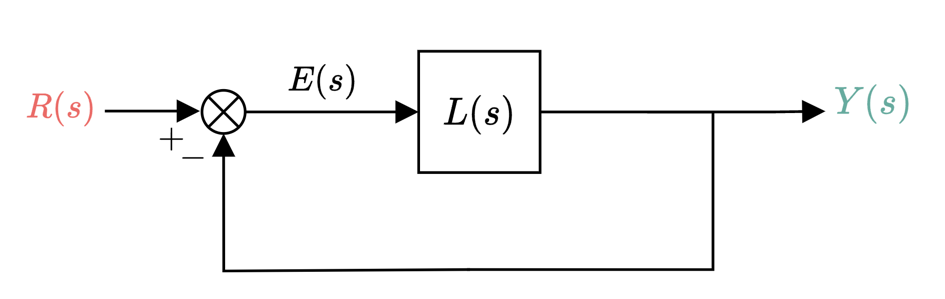

**Figure 9.2: **Closed-loop systems under consideration.

where the closed-loop relationship between $R(s)$ and $Y(s)$, namely the complementary-sensitivity function, is

$T(s)=\frac{L(s)}{1+L(s)}$.

The frequency response of $T(s)$ follows as

$T(j\omega)=\lim_{s\rightarrow j\omega}T(s)=\frac{L(j\omega)}{1+L(j\omega)}$.

Additionally, the frequency response magnitude (in arithmetic units) is 

$|T(j\omega)|=\frac{|L(j\omega)|}{|1+L(j\omega)|}$.

Given some frequency $\omega_{0}$, when $L(j\omega_0)=-1$, $|T(j\omega_0)|$ tends to infinity (the denominator of the above equation goes to zero, resulting in $|T(j\omega_0)|\rightarrow \infty$). In other words, under this condition, an input sinusoid with frequency $\omega_0$ will result in an infinitely large, unbounded output signal. This means that our closed-loop system will become marginally stable when $L(j\omega_0)=-1$, which based on our definition of bounded-input-bounded-output stability means that the closed-loop system is not strictly stable. We therefore need to avoid our loop frequency response from ever being $L(j\omega)=-1$. 

The "-1" quantity is known as the **critical point** and is an important means of assessing stability. The above interpretation means that if $L(j\omega)$, represented on a Nyquist plot, intersects the critical point (equal to $-1=e^{\pm j\pi}$) then our closed-loop system is not strictly stable. We can visualise the critical point on a Nyquist plot, as shown in Figure 9.3, which is located at $(-1,0)$.

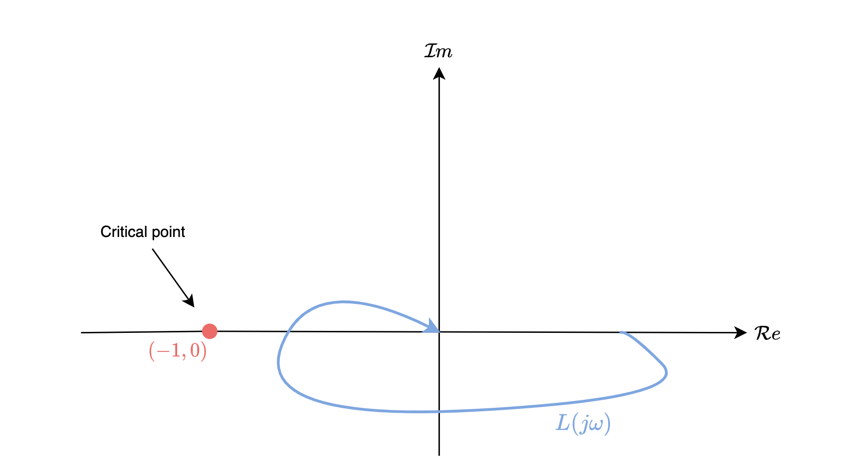

**Figure 9.3: **Visualisation of critical point in arithmetic complex plane.

clear
s = tf('s');
L = 1/(1+s)/(+s-3);
L=(1)/(s-2)

L =
 
    1
  -----
  s - 2
 
Continuous-time transfer function.
Model Properties


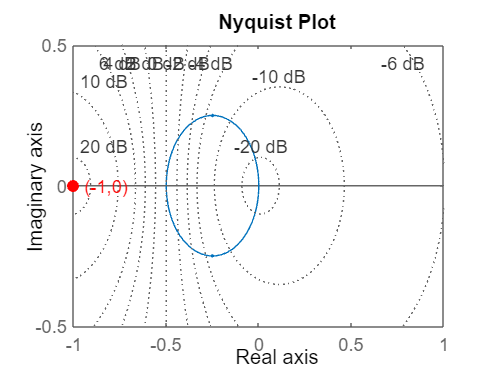


%W = linspace(0.1,1000,1e5);
%Lw = squeeze( freqresp(L,W) );


figure,hold on
nyquist(L)
%plot(real(Lw),imag(Lw),'-b')
%for i=1:200:2001
   % plot(real(Lw(i)),imag(Lw(i)),'ok',MarkerFaceColor='k')
   % text(real(Lw(i)),imag(Lw(i)),['  \omega= ',num2str(W(i),2)])
%end
plot(-1,0,'or',MarkerFaceColor='r')
text(-1,0,'  (-1,0)',Color='red')
title('Nyquist Plot')
xlabel('Real axis')
ylabel('Imaginary axis')
xlim([-1,1])
ylim([-0.5,0.5])
grid on

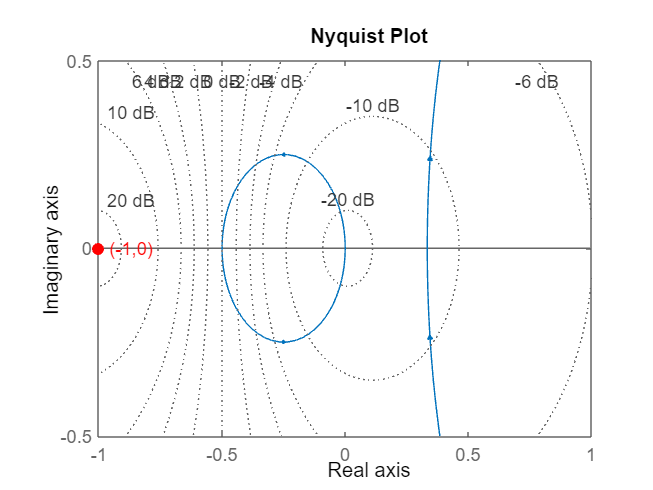

clear
H = tf([2 5 1],[1 2 3]);
nyquist(H)

#### Example

Consider the case of $L(s)=\frac{1}{s^2$ when placed in a feedback loop. The corresponding frequency response is given by $L(j\omega)=\frac{-1}{\omega^2}$. The loop transfer function's frequency response will therefore intercept the critical point when $\omega=1$. The code below shows the time-domain output response of $T(s)=\frac{L(s)}{1+L(s)}$ for a unit step input (top figure) and an input sinusoid of $r(t)=\sin(1t)$ (bottom figure).

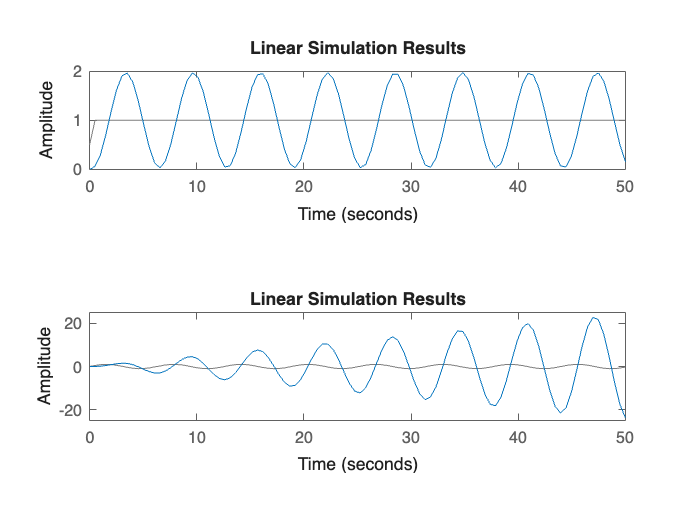

%Example
clear
s = tf('s');
L = 1/s^2;
T = feedback(L,1);

t = linspace(0,50,100);
figure
subplot(2,1,1),lsim(T,heaviside(t),t)
subplot(2,1,2),lsim(T,sin(t),t)

Note that we can determine our closed-loop system as

$T(s)=\frac{L(s)}{1+L(s)}=\frac{1/s^2}{1+1/s^2}=\frac{1}{s^2+1}$,

which is a marginally stable system with poles sitting at $p_{1,2}=\pm j$.

## 9.3 Closed-loop stability from open-loop frequency response

In this course we will only consider open-loop systems that are marginally or strictly stable when assessing closed-loop stability. That is, open-loop systems with poles in the closed left half-plane (CLHP). Under this condition, we can assess the closed-loop stability of our system using the frequency response, based on the so-called *Nyquist stability criterion* (we will not cover this in **MEC3079S**, but will rather just use one of the results without proof). 

### 9.3.1 Phase crossover frequency and gain crossover frequency

Before making use of the Nyquist stability criterion, we need to define two key frequencies, namely phase crossover frequency and gain crossover frequency.

The **phase crossover frequency**, $\omega_{pc}$, is defined as the frequency at which $\angle L(j\omega_{pc})=-180^\circ$. In other words, the frequency where the phase of the loop transfer function is equal to $-180^\circ$. The name is fairly literal in that $\omega_{pc}$ indicates the frequency at which the phase *crosses over* the $-180^\circ$ phase line. Note that not all systems will possess a phase crossover frequency.

The **gain crossover frequency**, $\omega_{gc}$, is defined as the frequency at which $| L(j\omega_{gc})|=1$ (or $| L(j\omega_{gc})|_{dB}=0$ dB in logarithmic units). In other words, the frequency where the loop transfer function has unit magnitude. The name refers to the frequency, $\omega_{gc}$, at which the gain *crosses over* the $1$ (or $0$ dB) gain line. Note that not all systems will possess a gain crossover frequency.

#### Example 1

*Determine the gain and phase crossover frequency of *$L(s)=\frac{10}{s+1}$.

The frequency response follows as $L(j\omega)=\frac{10}{j\omega+1}$. To calculate the gain crossover frequency, we determine the magnitude response and then set it to unity, followed by finding the corresponding frequency. Setting 

$|L(j\omega)|=\left|\frac{10}{j\omega+1}\right|=\left|\frac{10}{\sqrt{\omega^2+1}}\right|=1$,

 and solving for $\omega=\omega_{gc}$ yields $\omega_{gc}=\sqrt{99}\approx 9.95$ rad/s. We can confirm our result using the code below.

clear 
s = tf('s');

L=10/(s+1)

L =
 
   10
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties



w_gc = 9.95;    %determined gain crossover frequency w_gc
[Lmag_wgc,~] = bode(L,w_gc) %determine magnitude response at calculated gain crossover frequency, w_gc

Lmag_wgc = 1.0000

For phase crossover frequency, we set 

$\angle L(j\omega)= \angle\frac{10}{j\omega+1}=-\tan^{-1}\omega=-\pi$,

 and solve for $\omega=\omega_{pc}$. However, in this case no solution exists as $\tan^{-1}\omega$ is bounded by $\pm \pi/2$. Therefore no phase crossover frequency exists for $L(s)$. This should not be too surprising, as each pole/zero can only contribute up to $90^\circ$ of phase lag/lead.

#### Example 2

*Determine the gain and phase crossover frequency of *$L(s)=\frac{1}{s}e^{-5s}$.

The frequency response follows as $L(j\omega)=\frac{1}{j\omega}e^{-j5\omega}$. Setting 

$|L(j\omega)|=\left|\frac{1}{j\omega}e^{-j5\omega}\right|=\left|\frac{1}{j\omega}\right|=\left|\frac{1}{\omega}\right|=1$, 

and solving for $\omega=\omega_{gc}$ yields $\omega_{gc}=1$ rad/s. We can confirm our result using the code below.

clear 
s = tf('s');

L=1/s*exp(-5*s);

w_gc = 1;    %determined gain crossover frequency w_gc
[Lmag_wgc,~] = bode(L,w_gc) %determine magnitude response at calculated gain crossover frequency, w_gc

For phase crossover frequency, we set 

$\angle L(j\omega)= \angle\frac{1}{j\omega}e^{-j5\omega} = \angle\frac{1}{j\omega}-5\omega=-\frac{\pi}{2}-5\omega=-\pi$,

and solve for $\omega=\omega_{pc}$, which yields $\omega=\frac{\pi}{10}$ rad/s. We can confirm our result using the code below.

w_pc = pi/10;    %determined phase crossover frequency w_pc
[~,Langle_wpc] = bode(L,w_pc) %determine magnitude response at calculated phase crossover frequency, w_pc

### 9.3.2 Determining stability

According to the Nyquist stability criterion, given that $\omega_{pc}$ is the frequency that corresponds with $\angle L(j\omega_{pc})=\pm180^\circ$ (assuming such a frequency exists), if $|L(j\omega_{pc})|<1$, the system will be closed-loop stable. In other words, the gain of the open-loop transfer function must be less than unity when the phase angle is equal to $-180^\circ$. If the above-mentioned condition is not met, the closed-loop system will then be unstable. This includes if $L(j\omega_{pc})=-1$. Note that if a $\omega_{pc}$ does not exist that satisfies $\angle L(j\omega_{pc})=-180^\circ$, then the closed-loop system is still stable.

We can perform calculations to check for the above condition, but an easier approach is to visualise the frequency response data on an appropriate diagram (such as a Bode plot, Nyquist plot, or log-polar plot) and then visually assess whether the above condition is met. 

### 9.3.3 Stability from Nyquist diagrams

On a Nyquist plot, the phase crossover frequency occurs when the phase angle of $L(j\omega)$ is equal to $-180^\circ$. This corresponds to when the frequency response locus intersects the *negative-real axis*. Because the critical point is located a distance of 1 from the origin, if the intersection of the negative-real axis occurs to the *right* of the critical point, as shown for $L_1(j\omega)$, then $|L_1(j\omega_{{pc}_1})|<1$ and the corresponding closed-loop system $T_1(j\omega)$ will be stable. If the intersection of the negative-real axis occurs to the *left* of the critical point, as shown for $L_2(j\omega)$, then $|L_2(j\omega_{{pc}_2})|>1$ and based on Nyquist stability criterion, the corresponding $T_2(j\omega)$ will be unstable. In short, when represented on a Nyquist plot, we require that our frequency response locus does not encircle the critical point in order to ensure closed-loop stability. This is exemplified in Figure 9.4.

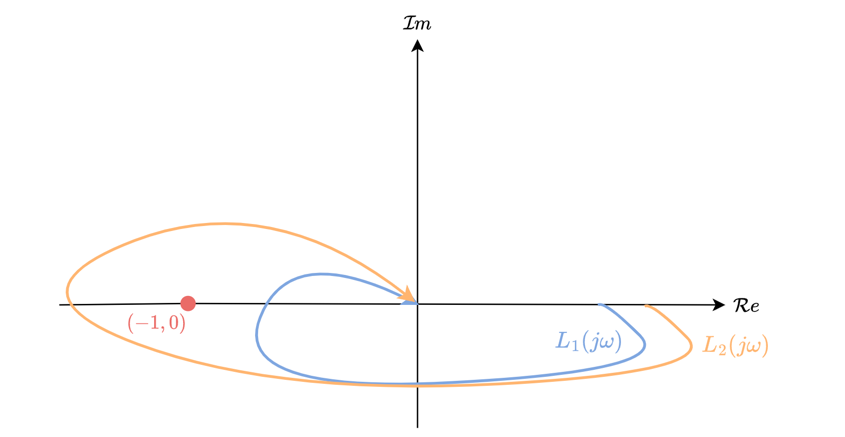

**Figure 9.4: **Visualisation of $L_2(j\omega)$ encircling critical point, which implies closed-loop instability, and $L_1(j\omega)$ not encircling critical point, which implies closed-loop stability.

### 9.3.4 Stability from Bode diagrams

For Bode diagrams, we begin by identifying the frequency, $\omega_{pc}$, at which the phase angle of our open-loop system is equal to $-180^\circ$, namely when $\angle L(j\omega_{pc})=-180^\circ$. Once we identify the frequency, we then check the corresponding magnitude response at $\omega_{pc}$ to see if the gain is less than unity: $|L(j\omega_{pc})|<1$. In the case of plotting magnitudes in decibels, this corresponds to checking whether $|L(j\omega_{pc})|_{dB}<0$ dB.

As shown in Figure 9.5, $T_1(s)$ will be stable based on $|L_1(j\omega_{pc})|_{dB}=-6<0$ dB, whereas $T_2(s)$ will be unstable based on $|L_2(j\omega_{pc})|_{dB}=2>0$ dB.

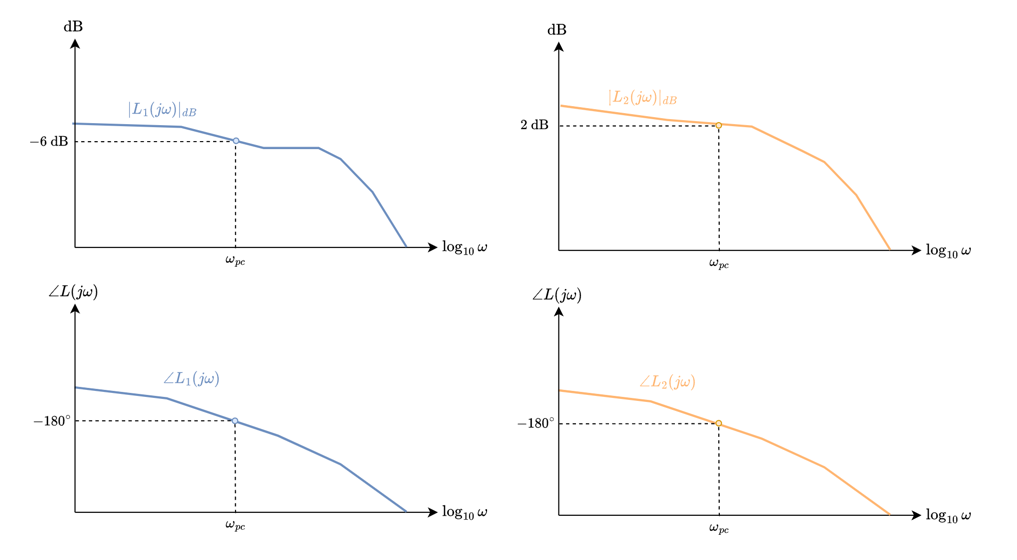

**Figure 9.5: **Visualisation of $L_2(j\omega)$ with less than unit gain at phase crossover frequency, which implies closed-loop instability, and $L_1(j\omega)$ with more than unit gain at phase crossover frequency, which implies closed-loop stability.

#### Example 1

The Bode plot of $L(s)=\frac{1}{s(1+s)^2}$ is generated using the code below.

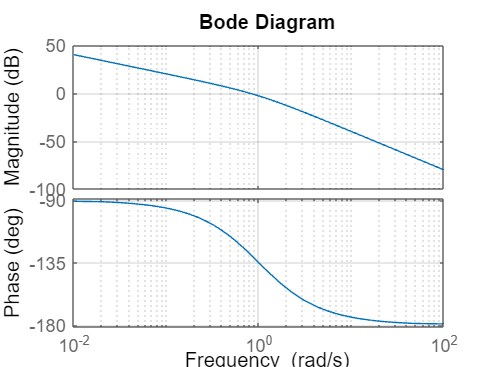

%Example
s = tf('s');
L = 1/s/(1+s)^2;

figure, clf
bode(L),grid on

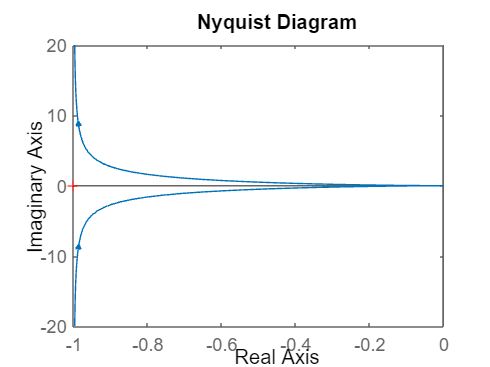

nyquist(L)

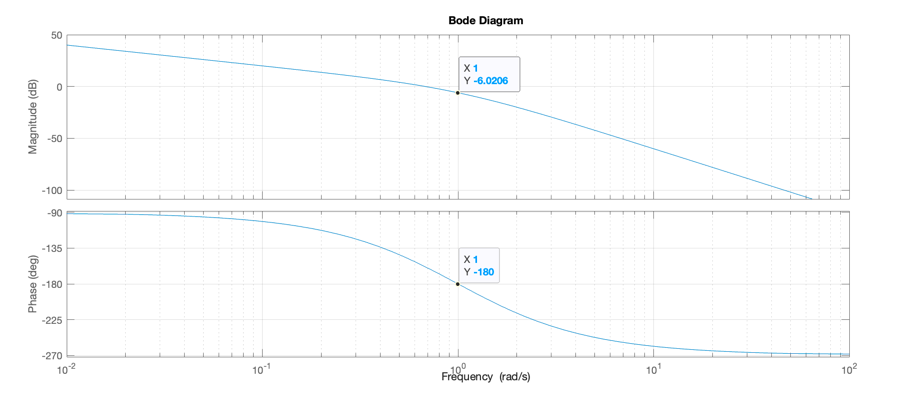

Based on the above Bode diagram, $\omega_{pc}=1$ rad/s. Consulting the Bode magnitude plot, $|L(j\omega_{pc})|_{dB}=|L(j1)|_{dB}=-6<0$ dB. Therefore $L(s)=\frac{1}{s(1+s)^2}$ will be *stable* when placed in a unity-feedback system, which is given by

$T(s)=\frac{L(s)}{1+L(s)}=\frac{1}{s^3+2s^2+s+1}$.

We can also check our closed-loop pole positions using the code below, which shows that all closed-loop poles reside in the open left half-plane.

T = feedback(L,1)

T =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.
Model Properties


pole(T)

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


We can also look at the step response, which shows that the output is bounded and converges to a steady-state value.

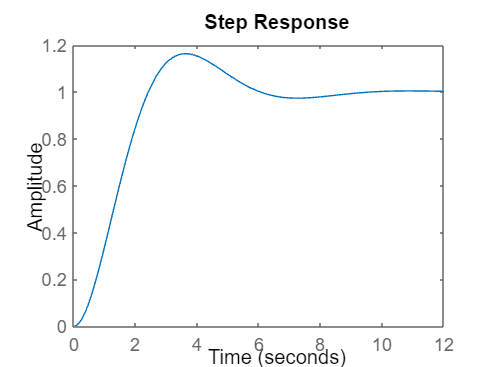

figure
step(T)

#### Example 2

The Bode diagram of  $L(s)=\frac{100}{s(1+s)^2}$ is generated using the code below. Note that this system has 100 times more gain than in **Example 1** but is otherwise identical. 

%Example
s = tf('s');
L = 100/s/(1+s)^2;

figure, clf
bode(L),grid on

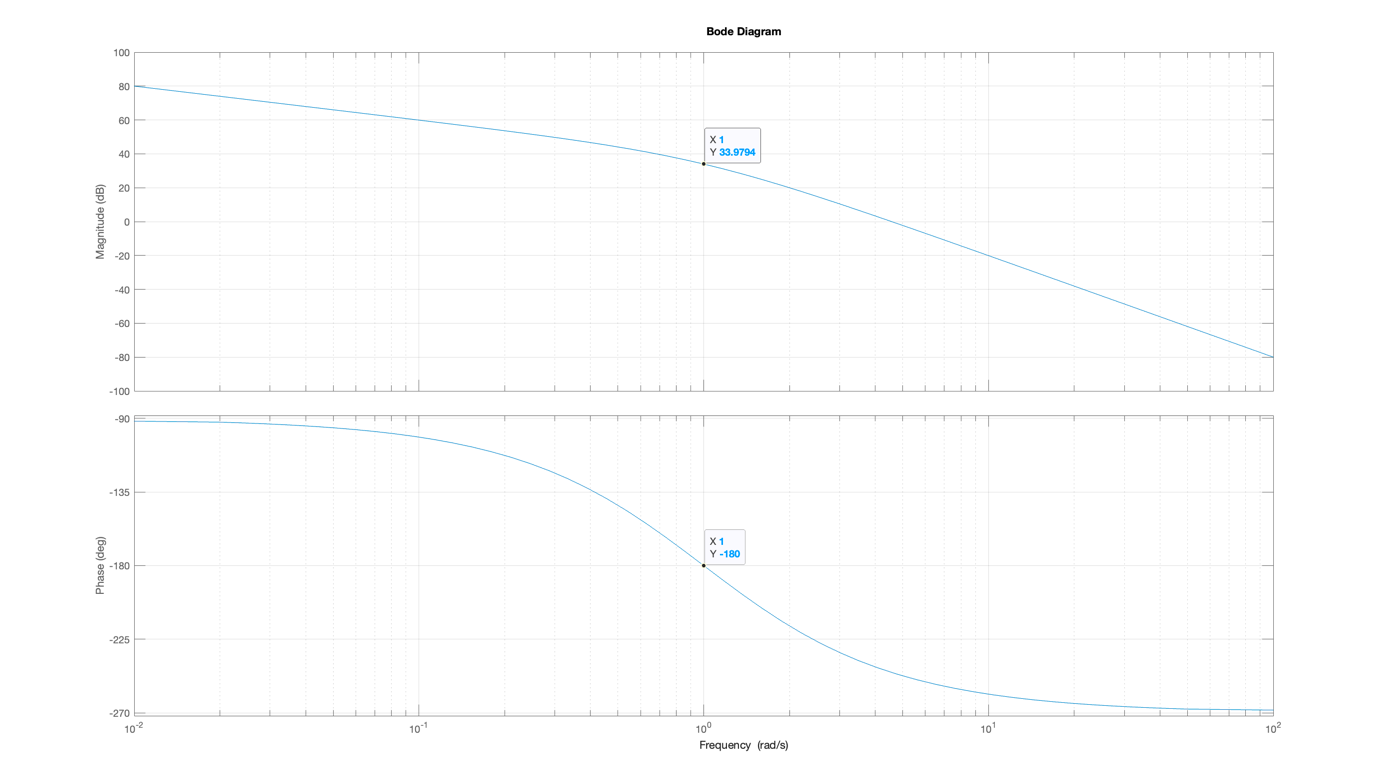

Based on the above Bode diagram, $\omega_{pc}=1$ rad/s (unchanged from before as the phase crossover frequency only depends on phase, and gain is the only thing that has changed in the system relative to **Example 1**). Consulting the Bode magnitude plot, $|L(j\omega_{pc})|_{dB}=|L(j1)|_{dB}=33.98>0$ dB. Therefore $L(s)=\frac{100}{s(1+s)^2}$ will be *unstable* when placed in a unity-feedback system, which is given by 

$T(s)=\frac{L(s)}{1+L(s)}=\frac{100}{s^3+2s^2+s+100}$.

We can also check our closed-loop pole positions using the code below, which shows that two closed-loop poles reside in the closed right half-plane.

T = feedback(L,1)
pole(T)

We can also look at the step response, which shows that the output response quickly starts blowing up.

figure
step(T)

### 9.3.5 Stability from log-polar plots

Log-polar plots can also be used to assess closed-loop stability based on the open-loop frequency response. Because the phase angle of $L(j\omega)$ is plotted against the (logarithmic) magnitude of $L(j\omega)$, all we need to do is check that the frequency response locus passes *below* the critical point of $-1$, which is represented on the log-polar plot by $(0~ \text{dB}, -180^\circ)$.

As shown in Figure 9.6, $T_1(s)$ will be stable based on the $L_1(j\omega)$ locus passing *below* the critical point (implying $|L_1(j\omega_{pc})|_{dB}<0$ dB), whereas $T_2(s)$ will be unstable based on the $L_2(j\omega)$ locus passing *above* the critical point (implying $|L_2(j\omega_{pc})|_{dB}>0$ dB).

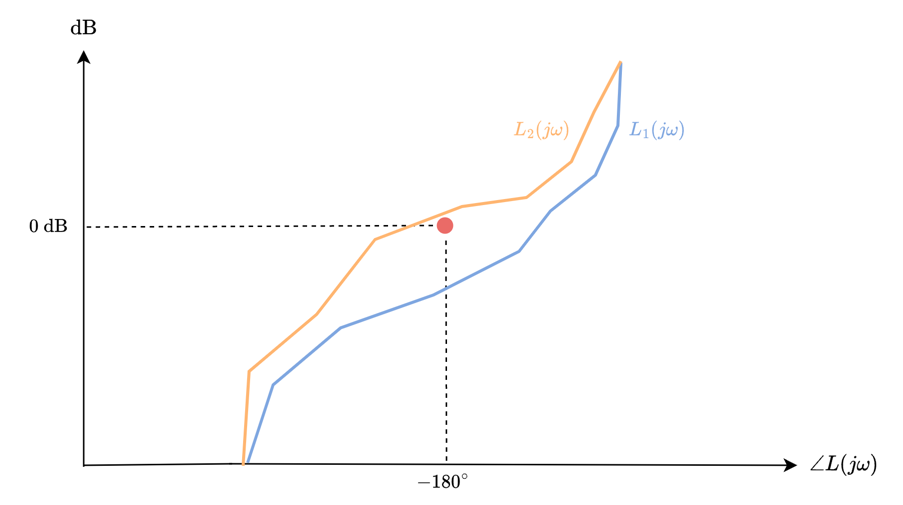

**Figure 9.6: **Visualisation of $L_2(j\omega)$ crossing above critical point, which implies closed-loop instability, and $L_1(j\omega)$ crossing below critical point, which implies closed-loop stability.

#### Example 1

The log-polar plot of  $L(s)=\frac{1}{s(1+s)^2}$ is generated using the code below.

%Example
s = tf('s');
L = 1/s/(1+s)^2;

figure, clf
nichols(L)

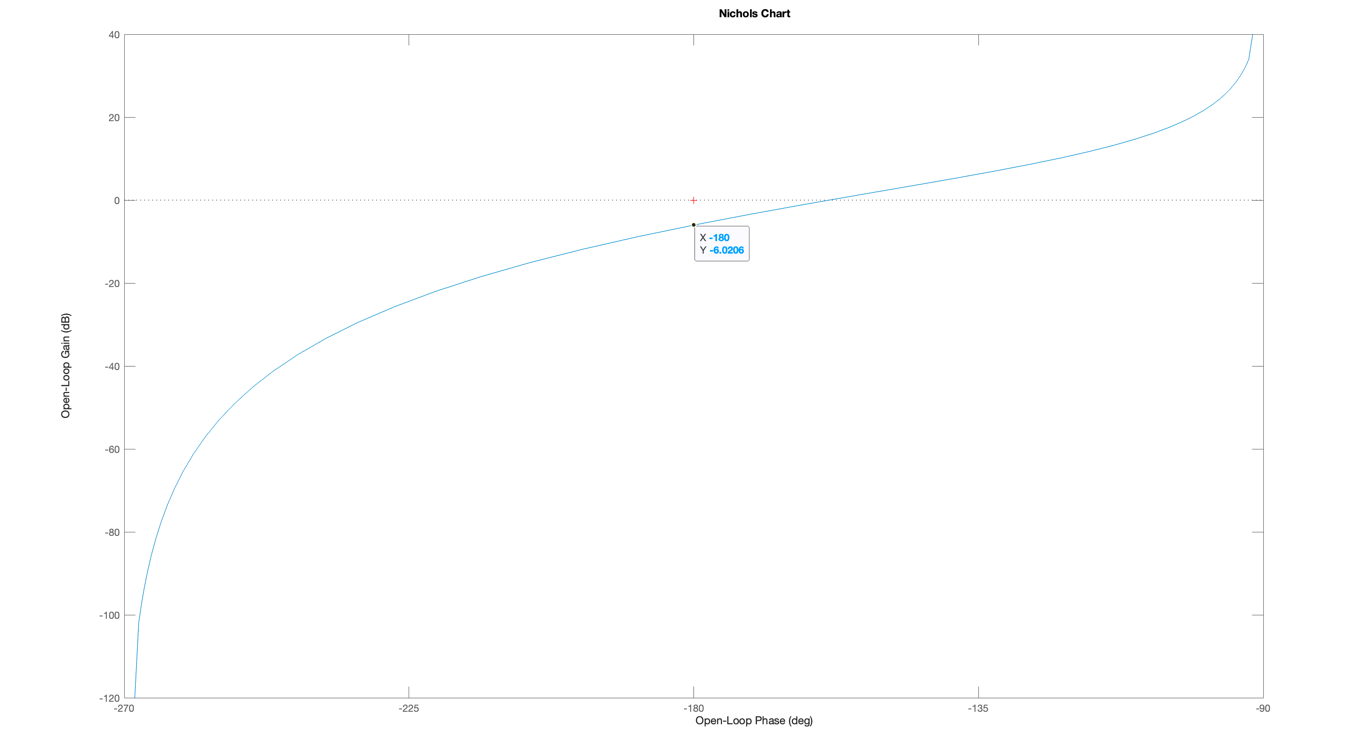

The curve passes *below* the critical point, indicated with a red "+" sign, which infers that the system will be *stable* in a closed-loop configuration. 

#### Example 2

The log-polar plot of $L(s)=\frac{100}{s(1+s)^2}$  is generated using the code below. Note that this system has 100 times more gain than in **Example 1** but is otherwise identical. 

%Example
s = tf('s');
L = 100/s/(1+s)^2;

figure, clf
nichols(L)

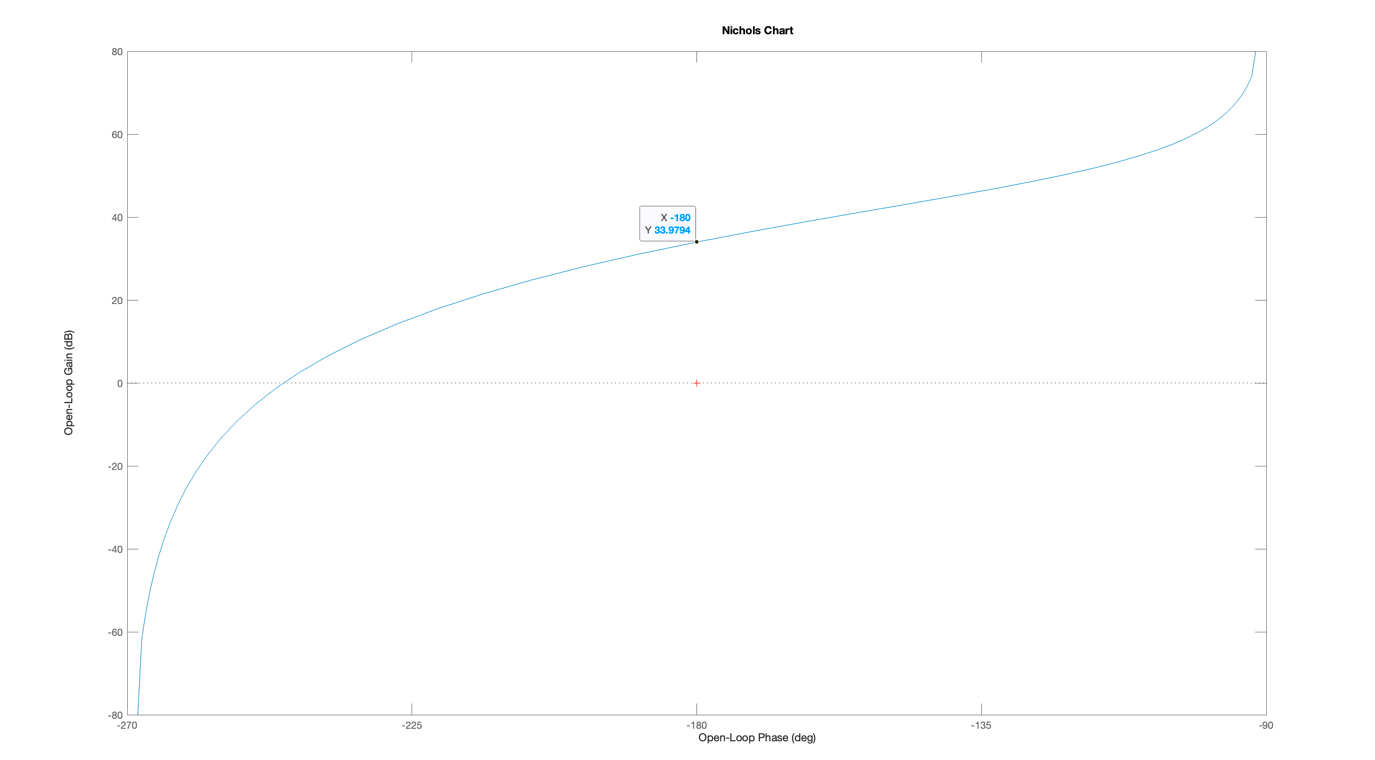

The curve passes *above* the critical point, indicated with a red "+" sign, which infers that the system will be *unstable* in a closed-loop configuration. 

## 9.4 Margins of stability

We have now identified a frequency response methodology that can determine whether an open-loop system will be strictly stable when placed in a feedback loop. In other words, we can draw conclusions about the stability of $T(s)$ if we know the frequency response of $L(s)$. However, in practice it is not enough that a system is stable. There must also be some "safety margins" of stability that quantify the extent to which the system is stable, and well as its robustness to perturbations. For example, a system may pass one of the tests above, but could be infinitesimally close to passing through the critical point. In this case, we should be a bit concerned about the stability of the closed-loop system, as any modelling imperfections, or minor parameter variations in the system may lead to instability. There are many ways to quantify our "confidence" of the closed-loop system's stability, but one of the most common approaches is the use of gain and phase margins, inspired by Nyquist’s stability criterion. 	 

The basic idea is that we want our frequency response to be sufficiently far from the critical point at all frequencies. We can have some handle of this using gain and phase margin, as explained below.

### 9.4.1 Gain margin and phase margin 

The **gain margin, **$G_M$, of a system is the smallest amount of gain increase (in dB) that the open-loop system can tolerate before the closed-loop system becomes unstable. For a system whose phase decreases monotonically as a function of frequency starting at $0^\circ$, the gain margin can be computed based on the smallest frequency where the phase of the loop transfer function is $-180^\circ$. As before, the frequency under consideration is the phase crossover frequency $\omega_{pc}$. Based on this, assuming the system is closed-loop stable, the gain margin is given by

$G_M = 20\log_{10} \frac{1}{|L(j\omega_{pc})|}=-20\log_{10} {|L(j\omega_{pc})|}=-{|L(j\omega_{pc})|}_{dB}$.

If the loop transfer function does not possess a phase crossover frequency (as a result of never having a phase of $-180^\circ$), then the system is said to have an *infinite* *gain margin*. This implies that (in theory!) any amount of gain can be added to the system without resulting in closed-loop instability. Gain margins are often required to be in the range of $2-5$ in arithmetic units, which corresponds with $6-14$ dB. However, this can vary depending on the system and application.

The **phase margin, **$\phi_M$, is the smallest amount of phase lag (in degrees) that the open-loop system can tolerate before the closed-loop system becomes unstable. The frequency under consideration is the gain crossover frequency, $\omega_{gc}$. The phase margin is given by

$\phi_M = \pi+\angle L(j\omega_{gc})$.

Phase margins are often required to be in the range of $30^\circ-60^\circ$. As with the gain margin specifications, this can vary depending on the system and application.

For a Bode diagram, the gain margin corresponds with the amount of gain required to raise the magnitude curve to $0$ dB when the phase angle is $\pm 180^\circ$, which occurs at the phase crossover frequency $\omega_{pc}$. The phase margin (in degrees) corresponds to the amount of phase required to lower the phase curve to $\pm 180^\circ$ when the magnitude is $0$dB, which occurs at the gain crossover frequency $\omega_{gc}}$. This is illustrated in Figure 9.7.

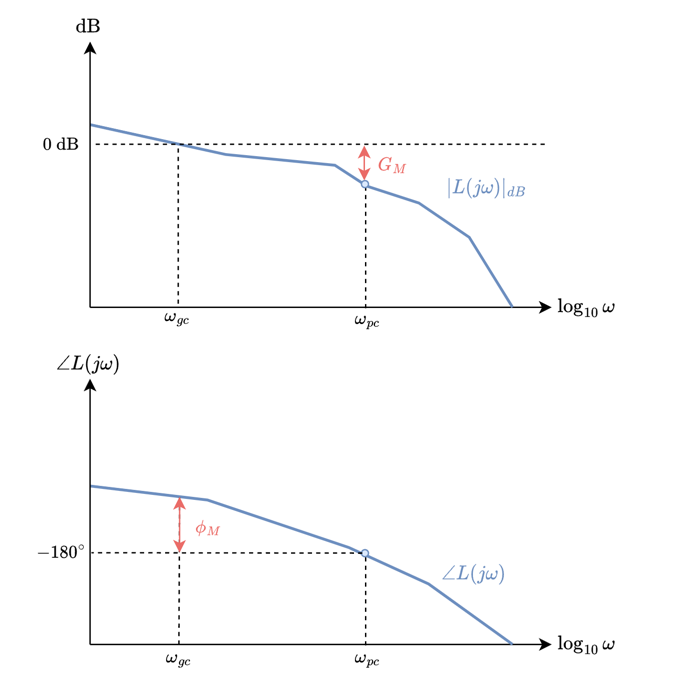

**Figure 9.7: **Visual representation of gain and phase margin on Bode diagram.

Note that in either case we are assessing how much gain or phase is required to make the frequency response have a value of $L(j\omega)=-1$, which corresponds with intercepting the critical point.

#### Example 

Determine the gain and phase margins of $L(s)=\frac{1}{s(1+s)^2}$.

The code below generates the Bode diagram of $L(s)$. 

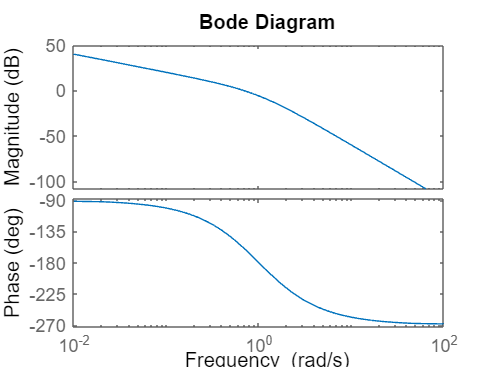

%Example
s = tf('s');
L = 1/(s*(1+s)^2);

figure, clf
bode(L)

[Gm,Pm,Wcg,Wcp] = margin(L)%function that generates a Bode diagram but also indicates the gain and phase margins

Gm = 2

Pm = 21.3877

Wcg = 1

Wcp = 0.6823

The gain and phase margins can be read off the plots and indicates that the system has a gain margin and phase margin of $G_M=6$ dB and $\phi_M=21.4^\circ$, respectively.

When using a log-polar plot, the gain margin corresponds with the amount of gain required to raise the curve such that it passes through the critical point, which occurs at the phase crossover frequency $\omega_{pc}$. The phase margin (in degrees) corresponds to the amount of phase required to shift the curve leftwards such that it passes through the critical point, which occurs at the gain crossover frequency $\omega_{gc}}$. This is illustrated in Figure 9.8.

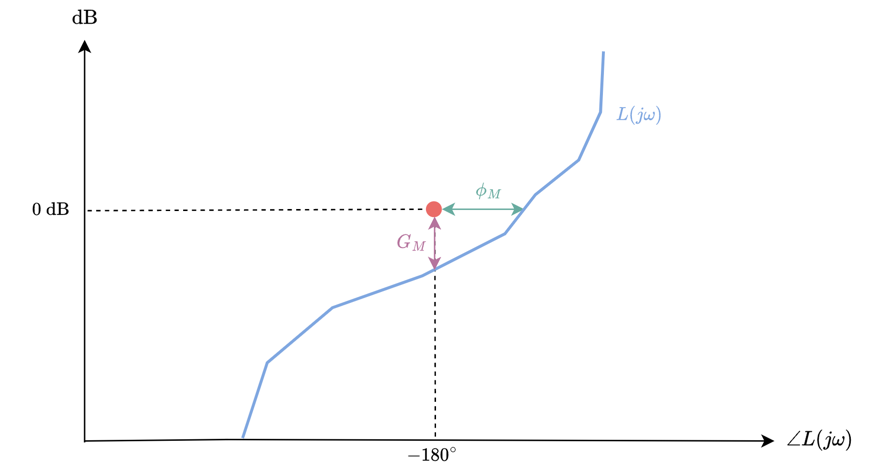

**Figure 9.8: **Visual representation of gain and phase margin on Log-polar plot

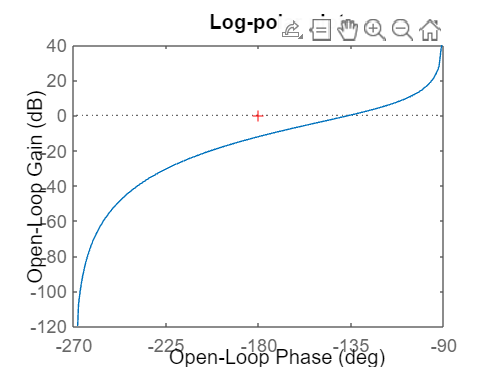

%Example
s = tf('s');
L = (-0.5+1)/s/(1+s)^2;

figure, hold on
nichols(L)
title('Log-polar plot')

[Gm,Pm,Wcg,Wcp] = margin(L)

Gm = 4

Pm = 44.0607

Wcg = 1

Wcp = 0.4238

A gain margin of $6$ dB corresponds to an arithmetic gain of $10^{6/20}\approx 2$. We should therefore expect that our closed-loop system will be destabilised if we add a gain of $2$ or more to $L(s)$. This is demonstrated using the code block below, where for values of $k\geq 2$, 


$$T_k(s)=\frac{kL(s)}{1+kL(s)}$$
 

will become unstable, as shown with the resulting step responses.

%Example
s = tf('s');
L = 1/s/(1+s)^2;

k = 2.1;

T = feedback(L,1);
Tk = feedback(k*L,1);

figure, hold on
step(T,50)
step(Tk,50)
legend('y(t)','y_k(t)')

### 9.4.2 Stability margin

The gain and phase margins are useful metrics to determine the loop transfer function's distance away from the critical point, and hence its level of stability. This is especially important when dealing with plant uncertainty (which is touched on in a later chapter). Specifically, we are working with an approximate model of our open-loop system, but the actual system that we are trying to control in feedback may have a different gain and phase profile, or have parameters that vary with time — hence the need for a gain and phase margin to give us some headroom in case our model is off. 

A drawback of gain and phase margin is that each quantity is treated independently of the other. In other words, gain margin considers gain variations when the phase remains unchanged at $-180^\circ$, and the phase margin considers phase variations without changing the unitary gain. Real-world systems are vulnerable to simultaneous gain and phase variations, which may not be adequately captured by the traditional gain and phase margin specifications. A fairly extreme example is shown below.

#### Example

Consider the loop transfer function, $L(s)=0.38\frac{s^2+0.1s+0.55}{s(s+1)(s^2+0.06s+0.5)}$. The log-polar plot of $L(s)$ is generated using the code below.

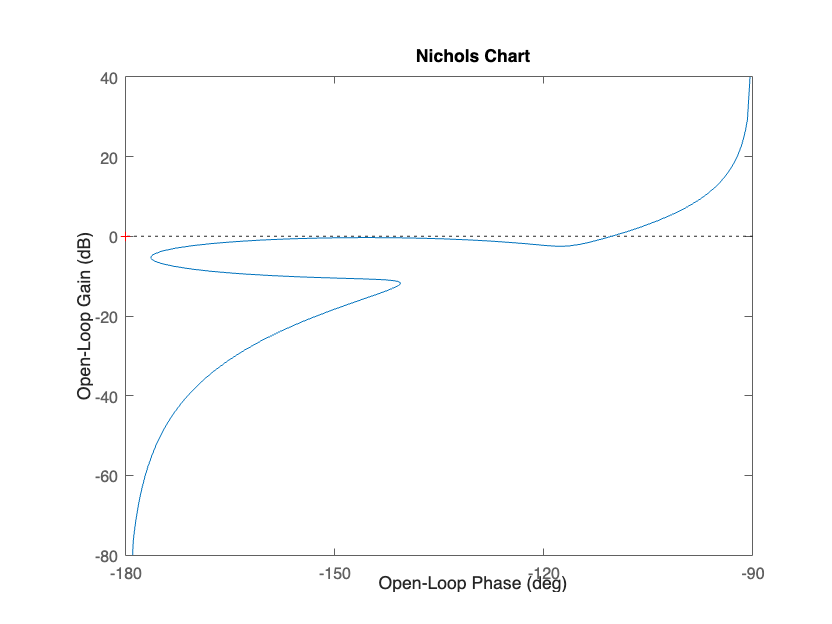

%Example
s = tf('s');
L = 0.38*(s^2+0.1*s+0.55)/s/(s+1)/(s^2+.06*s+0.5);

figure,clf
nichols(L)


[gm,pm] = margin(L)

gm = Inf

pm = 69.7721

The above system has an infinite gain margin and $~70^\circ$ phase margin, which gives us an impression that $L(j\omega)$ is far away from the critical point and quite safe from becoming unstable. However, visualisation on the log-polar plane shows that the frequency response locus actually comes very close to the critical point.

A more robust way of quantifying stability is to determine how close the frequency response comes to the critical point across all frequencies. Formally, we are trying to determine the Euclidean distance between the critical point of $-1$ and $L(j\omega)$, which can be written as

$|L(j\omega)-(-1)|=|L(j\omega)+1|$,

and then find the smallest $|L(j\omega)+1|$ across all frequencies ($\forall \omega\geq0$). In order to determine the smallest distance between the critical point and $L(j\omega)$, we can draw a circle on the Nyquist plot, centred at the critical point, and when the circle first intersects the $L(j\omega)$ locus, the corresponding radius is equal to the smallest distance, as shown in Figure 9.9.

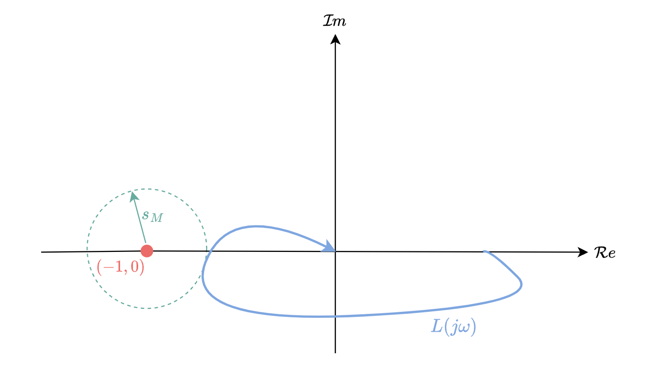

**Figure 9.9: **Visual representation of stability margin on arithmetic complex plane.

We refer to this radius as our **stability margin**, $s_M$, which considers both gain and phase variations in the open-loop system. This value is easy to read off a Nyquist plot, but is not always intuitive on a Bode diagram or log-polar plot, based on the logarithmic scale. That being said, in **Chapter 11** we will relate the stability margin with performance specifications on a log-polar plot, which will form the basis of our control design technique in this course. Reasonable stability margins are in often in the range of $0.5-0.8$.

## 9.5 Conditional stability

Stable open-loop systems with lots of low frequency phase lag (for example from multiple integrators) may have a phase angle of less than $-180^\circ$ well before the gain-cross over frequency, $\omega_{gc}$. In these systems, the closed-loop system can become unstable if the gain is too *low. *In this scenario, closed-loop stability is therefore **conditional** on the system having enough gain. 

#### Example

The log-polar plot of $L(s)=\frac{0.1(1+s)(1+s/0.1)}{s^3(1+s/5)^2}$ is generated using the code below.

clear 
s = tf('s');

L = 0.1*(1+s/1)*(1+s/0.1)/s^3/(1+s/5)^2

L =
 
  2.5 s^2 + 2.75 s + 0.25
  -----------------------
  0.1 s^5 + s^4 + 2.5 s^3
 
Continuous-time transfer function.
Model Properties


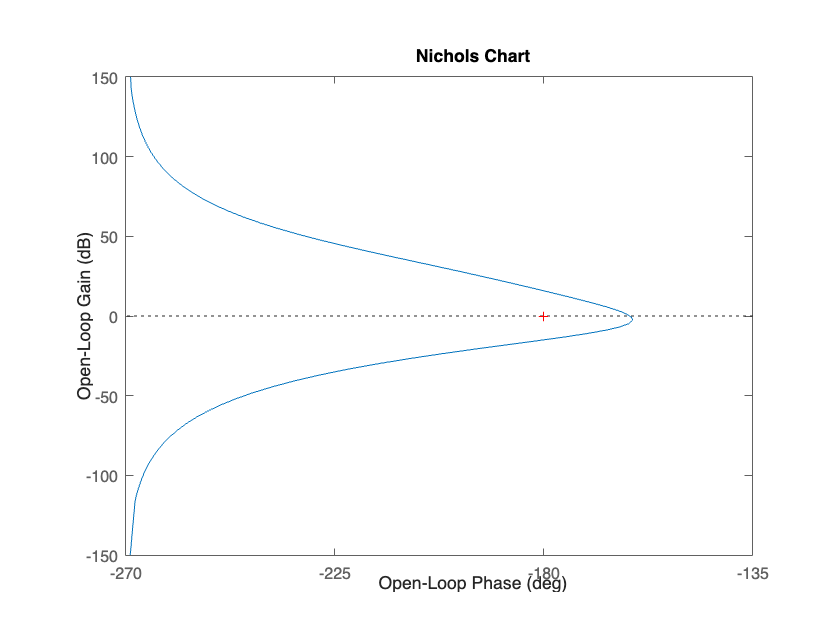


figure,clf
nichols(L)

$L(j\omega)$ has a phase angle of $-180^\circ$ at two frequencies, with the lower frequency corresponding with a magnitude response of approximately $16$ dB. If we were to now reduce the gain of $L(s)$ by approximately $10^{16/20}\approx 6.3$, then our closed-loop system will become unstable. The code below can be used to illustrate this behaviour, where increasing $a$ to $6.3$ and above results in an intersection of the critical point, resulting in instability. 

a = 6.3

a = 6.3000

10^(16/20)

ans = 6.3096

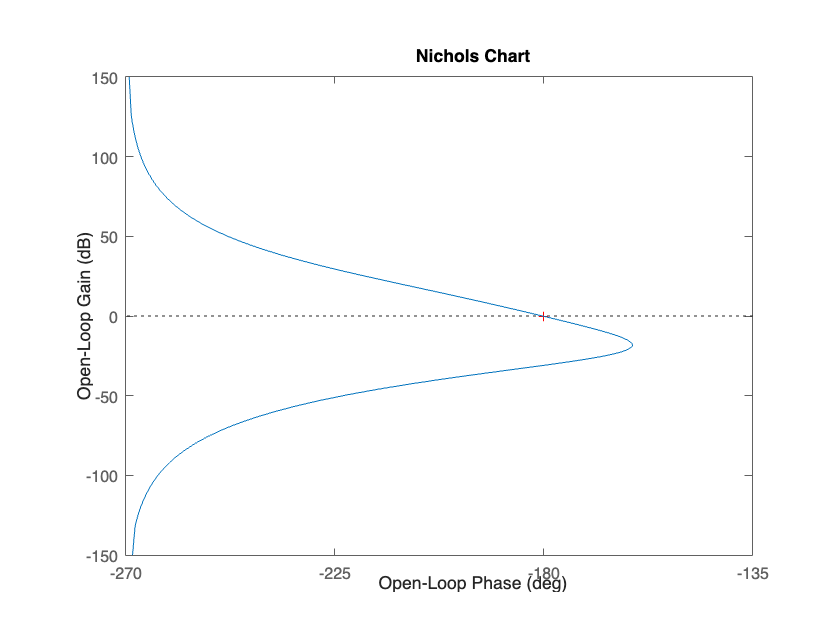

figure,clf
nichols(L/a)

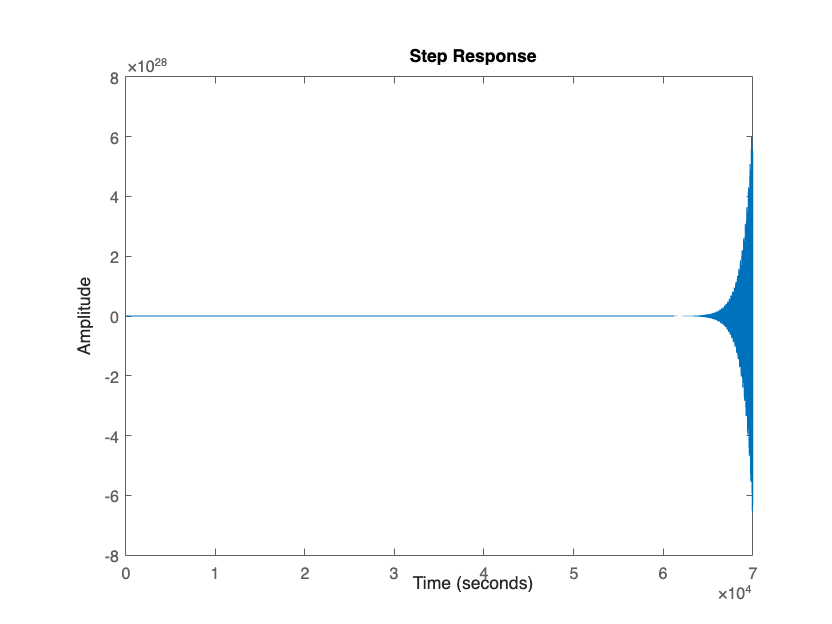


T = feedback(L/a,1);
figure
step(T)

Any further gain reduction will still result in an unstable closed-loop system, as there is no encirclement of the critical point. Unlike unconditionally stable systems, a **conditionally stable** system can therefore be thought of as a system that is only stable for sufficiently large loop gain.

### 9.5.1 Negative gain margin	

In the case of conditionally stable systems, the system will have a **negative gain margin** (in dB), which indicates the amount of gain reduction in $L(s)$ that can be tolerated before the corresponding closed-loop system becomes unstable. Conditionally stable systems may therefore possess both a positive gain margin (what we determined in previous sections) and negative gain margin, which results in a finite region of conditional stability.

Systems with negative gain margin can be quite problematic in real-world systems. This is because saturation of the control action, $u(t)$, results in the loop transfer function's gain to reduce to zero, which means that encirclement of the critical point will no longer take place. Another real-world issue of conditionally stable systems is if there is a temporary hardware/software fault (e.g. communications delay) that results in the feedback loop remaining open (effectively setting the loop gain to zero), which again would result in de-stability). There are ways of designing nested feedback controllers such that negative gain margin is always prevented, but this will not be covered in detail in this course.